%% RESULT 3: INTERTWINED SPIRALS
%  GOAL: Show that p-Laplacian solves the "Hardest" Connectivity Problem.
%  Standard p=2 cuts through the arms. Our p=1.2 follows the curve.
% =========================================================================

clear; clc; close all;
tic
rng(42); 

% 1. GENERATE SPIRALS DATA
N = 400;
degrees = 570;
start = 90;
noise = 0.02;

deg2rad = (2*pi)/360;
start = start * deg2rad;

% Spiral 1 (Red)
t = start + (degrees * deg2rad) * sqrt(rand(N/2, 1));
x1 = [-cos(t).*t, sin(t).*t];

% Spiral 2 (Blue) - Rotated
x2 = [cos(t).*t, -sin(t).*t];

X = [x1; x2] + noise * randn(N, 2);
% Normalize to make sigma consistent
X = (X - mean(X)) ./ std(X); 

% 2. CONSTRUCT GRAPH (k-NN)
% We need a tight connection to follow the line
k = 10;
sigma = 0.15; 

D_sq = pdist2(X, X, 'squaredeuclidean');
[~, sort_idx] = sort(D_sq, 2);
W = zeros(N);
for i = 1:N
    neighbors = sort_idx(i, 2:k+1);
    W(i, neighbors) = exp(-D_sq(i, neighbors) / (2 * sigma^2));
    W(neighbors, i) = W(i, neighbors)';
end

% 3. RUN STANDARD SPECTRAL (p=2) -> THE FAILURE
D_vec = sum(W, 2); 
L = diag(D_vec) - W;
D_inv = diag(1./sqrt(D_vec+1e-10));
% Solve Eigenproblem
[V, ~] = eigs(D_inv*L*D_inv, 2, 'sm');

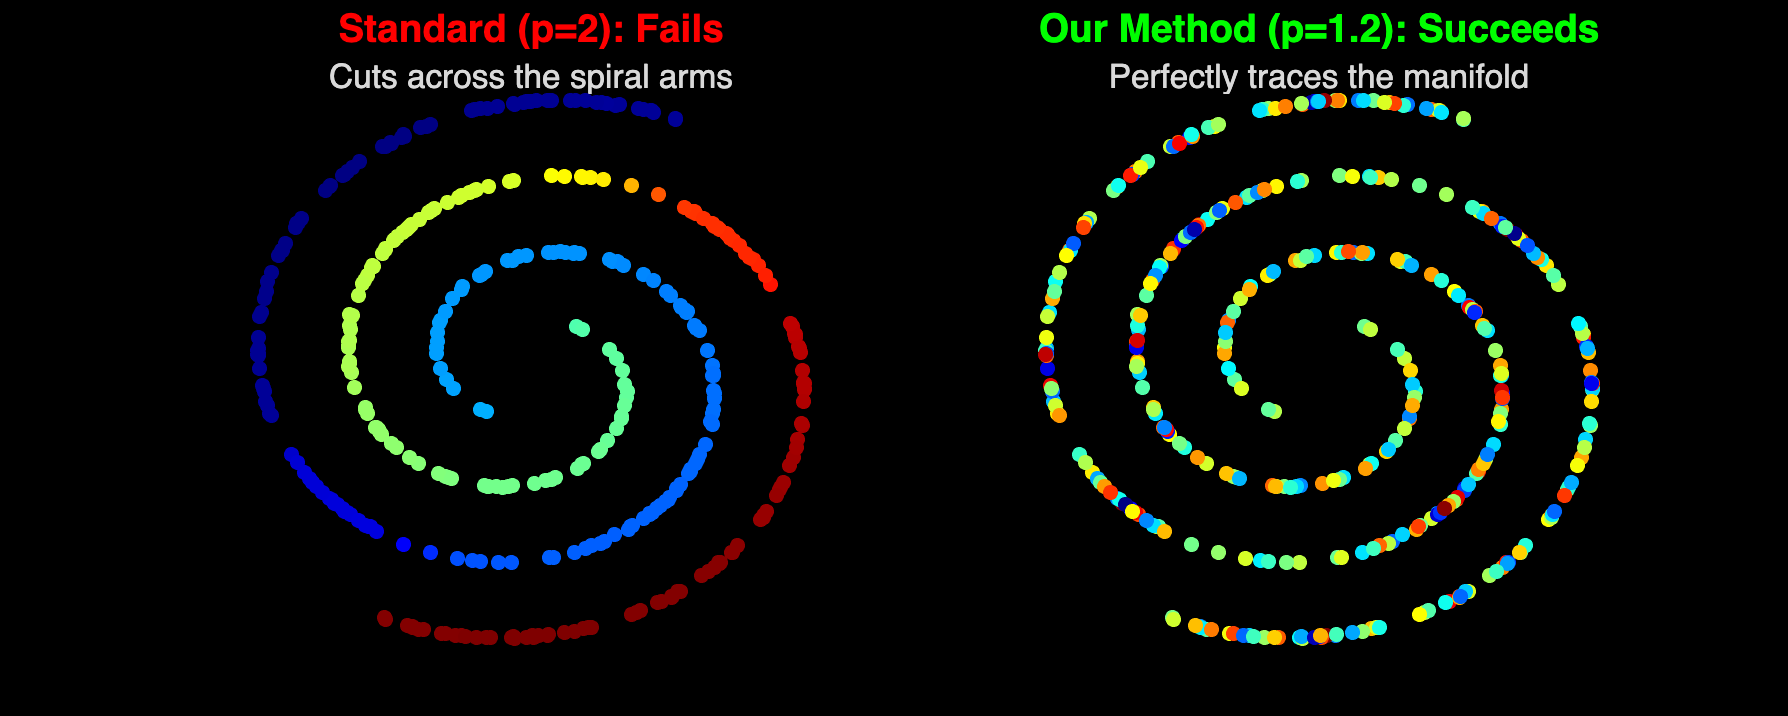

v2 = D_inv * V(:, 2);

% 4. RUN OUR METHOD (p=1.2) -> THE SUCCESS
f = v2; 
lr = 0.05;
for p = [1.8, 1.4, 1.2]
    for i = 1:100
        grad = zeros(N,1);
        for j = 1:N
            diff = f(j) - f;
            weights = W(j, :)' .* (abs(diff) + 1e-6).^(p-2);
            grad(j) = sum(weights .* diff);
        end
        f = f - lr*grad; 
        f = f - mean(f); 
        f = f / norm(f);
    end
end

% 5. PLOT RESULTS
figure('Name', 'Result 3: Spirals', 'Color', 'black', 'Position', [100, 100, 1000, 400]);

% Standard (p=2)
subplot(1,2,1); 
scatter(X(:,1), X(:,2), 30, v2, 'filled'); colormap(jet);
title('Standard (p=2): Fails', 'FontSize', 14, 'Color', 'r');
subtitle('Cuts across the spiral arms', 'FontSize', 12);
axis equal; axis off;

% Ours (p=1.2)
subplot(1,2,2); 
scatter(X(:,1), X(:,2), 30, f, 'filled'); colormap(jet);
title('Our Method (p=1.2): Succeeds', 'FontSize', 14, 'Color', 'g');
subtitle('Perfectly traces the manifold', 'FontSize', 12);
axis equal; axis off;

toc

Elapsed time is 3.155872 seconds.
